# Flux Balance Analysis (FBA)

## Author(s): **Vanja Vlasov, **Marouen Ben Guebila, **Systems Biochemistry Group, LCSB, University of Luxembourg, **

## **Thomas Pfau, Systems Biology Group, LSRU, University of Luxembourg** 

##  Reviewer(s): Ines Thiele, **Systems Biochemistry Group, LCSB, University of Luxembourg**

## **Thomas Pfau, Systems Biology Group, LSRU, University of Luxembourg** 

## INTRODUCTION

Flux balance analysis (FBA), one of the most used modelling approaches for metabolic systems, evaluates the metabolic flux distribution$$^1$. 

Applications of FBA for molecular systems biology include prediction of the growth rates, uptake rates, knockout lethality and product secretion. In FBA, the solution space is constrained by the assumption of a steady-state, under which each internal metabolite is consumed at the same rate as it is produced.

For the quantitative estimation of the metabolic fluxes, linear programming (LP) can be used to solve the stoichiometric matrix for a given objective function under different constraints. The constraints of the problem depict the space of all eligible possibilities from which an optimal solution can be selected. 


$$\begin{array}{ll}
\min\limits _{v} & \ c^{T}v\\
\text{s.t.} & Sv=b,\\
 & l\leq v\leq u,
\end{array}$$


where $$c\in\Re^{n}$$ is a parameter vector that linearly combines one or more reaction fluxes to form what is termed the objective function,  and where a $$b_{i}<0$$, or  $$b_{i}>0$$, represents some fixed output, or input, of the ith molecular species. $$S\in\Re^{m\times n}$$ is a stoichiometric matrix for $$m$ molecular species and $$n$ reactions, and $$b$ is a vector of known metabolic exchanges. The output of FBA is a particular flux distribution, $$v$ , which maximises or minimises the objective function and stands between upper and lower bounds, $$u$ and $$l$, respectively.

There are multiple different variants of FBA which will be discussed here:

- **Standard FBA**

- **Sparse FBA**

- **Metabolite dilution FBA (mdFBA)**

- **Geometric FBA**

- **Parsimonious enzyme usage Flux Balance Analysis (pFBA)**

- **Dynamic FBA**

- **Relax FBA**

- **Flux enrichment analysis (FEA)**

## EQUIPMENT SETUP

If necessary, initialise the cobra toolbox:

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

For solving linear programming problems in FBA analysis, certain solvers are required:

% solverOK = changeCobraSolver(solverName, solverType, printLevel, unchecked)

The present tutorial can run with [glpk package](https://opencobra.github.io/cobratoolbox/deprecated/docs/cobra/solvers/changeCobraSolver.html), which does not require additional installation and configuration. Although, for the analysis of large models is recommended to use the [GUROBI](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md) package.

Setup the appropriate solver for the machine you are using by removing the "%" (comment) sign for only the desired solver.

% changeCobraSolver('glpk','all');
% changeCobraSolver('tomlab_cplex','all');
% changeCobraASolver('ibm_cplex','all');
 changeCobraSolver ('gurobi', 'all', 1);


 > Gurobi interface added to MATLAB path.
 > Solver for LPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MILPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for QPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MIQPproblems has been set to gurobi.
 > Solver gurobi not supported for problems of type NLP. Currently used: matlab 


## PROCEDURE

Before proceeding with the simulations, the path for the model needs to be set up:

% check if Recon3 exists:
% pathModel = '~/work/sbgCloud/data/models/unpublished/Recon3D_models/';
% filename = '2017_04_28_Recon3d.mat';
% load([pathModel, filename])
% model = modelRecon3model;
% clear modelRecon3model
% and if not
% select your own model, or use Recon2.0model instead filename='Recon3.0model';
global CBTDIR
load([CBTDIR filesep 'test' filesep 'models' filesep 'Recon2.0model.mat']);
model = Recon2model;
model.rxns = strrep(model.rxns, '(', '[');
model.rxns = strrep(model.rxns, ')', ']');
clear Recon2model

In this tutorial, the provided model is a generic model of the human cellular metabolism, Recon 3D$$ ^2$. Therefore, we assume, that the cellular objectives include energy production or optimisation of uptake rates and by-product secretion for various physiological functions of the human body.

The metabolites structures and reactions are from the Virtual Metabolic Human database (VMH, [http://vmh.life](http://vmh.life)).

## Standard FBA

Standard FBA allows prediction of a cellular objective for a given set of constraints. These constraints can include e.g. uptake and release limits, or minimal and maximal reaction fluxes.

## TIMING

The time to determine a FBA solution depends on the size of the genome-scale model and is commonly less than a second for a medium sized model.

- *Calculating maximal ATP energy production under aerobic condition *

For each new simulation, the original model will be copied to a new variable. This preserves the constraints of the original model and allows to perform simulations with new constraints. Additionally, this method of renaming the model avoids confusion while performing multiple simulations at the same time.

modelaerobic = model;

The ATP demand reaction, i.e., [`DM_atp_c_`](http://vmh.life/#human/all/DM_atp_c_) within the model is a reaction that involves hydrolysis of ATP to ADP, Pi and proton in the cytosol. 

 printRxnFormula(model, 'DM_atp_c_');

DM_atp_c_	h2o[c] + atp[c] 	->	adp[c] + h[c] + pi[c] 


We will set this reaction as our objective with the `'changeObjective'` command. Maximising the flux through this reaction will result in the remaining network producing a maximal amount of ATP (up to the limit of the reaction).

modelaerobic = changeObjective (modelaerobic, 'DM_atp_c_');

The glucose and oxygen, in this case, are provided in high amounts for calculating the flux through ATP demand. 

The `'changeRxnBounds' `command changes the lower ('`l`'), upper ('`u`'), or both the bounds ('`b`') for the specified reaction. Here we fix the glucose uptake to 20 $\mu$mol/min/g of proteins and allow a maximal uptake of oxygen of 1000 $\mu$mol/min/g of proteins. The oxygen uptake flux is basically unconstrained. 

% For Recon3.0 model
% modelaerobic = changeRxnBounds (modelaerobic, 'EX_glc_D[e]', -20, 'l');
modelaerobic = changeRxnBounds (modelaerobic, 'EX_glc[e]', -20, 'l');
modelaerobic = changeRxnBounds (modelaerobic, 'EX_o2[e]', -1000, 'l');

The `optimizeCbModel()` calculates one of the optimal solutions within the defined solution space, wherein, the output can be either maximum or minimum flux through the defined objective, whichever is desired. In the above example, the maximal flux through the [`DM_atp_c_`](http://vmh.life/#human/all/DM_atp_c_) is desired. 

FBAaerobic = optimizeCbModel (modelaerobic, 'max')

FBAaerobic =          full: [7440×1 double]
          obj: 1000
        rcost: [7440×1 double]
         dual: [5063×1 double]
       solver: 'gurobi'
    algorithm: 'default'
         stat: 1
     origStat: 'OPTIMAL'
         time: 0.1653
        basis: [1×1 struct]
            x: [7440×1 double]
            f: 1000
            y: [5063×1 double]
            w: [7440×1 double]
            v: [7440×1 double]


## ANTICIPATED RESULTS

When oxygen and all external and internal carbon sources are provided and open in the model of the human cell metabolism, the flux through ATP demand reaction is high 1000 $\mu$mol/min/g of proteins. 

## TROUBLESHOOTING

If there are multiple energy sources available in the model; Specifying more constraints is necessary. If we do not do that, we will have additional carbon and oxygen energy sources available in the cell and the maximal ATP production. 

To avoid this issue, all external carbon sources need to be closed.

%Closing the uptake of all energy and oxygen sources
idx=strmatch('Exchange/demand reaction',model.subSystems);
c=0;
for i=1:length(idx)
    if model.lb(idx(i))~=0
        c=c+1;
        uptakes{c}=model.rxns{idx(i)};
    end
end
% If you use Recon3.0 model, than:
% modelalter = model;
% modelalter = changeRxnBounds(modelalter, uptakes, 0, 'b');
% modelalter = changeRxnBounds(modelalter, 'EX_HC00250[e]', -1000, 'l');

% The alternative way to do that, in case you were using another large model, 
% that does not contain defined Subsystem is
% to find uptake exchange reactions with following codes:
% [selExc, selUpt] = findExcRxns(model);
% uptakes1 = model.rxns(selUpt);

% Selecting from the exchange uptake reactions those 
% which contain at least 1 carbon in the metabolites included in the reaction:
 subuptakeModel = extractSubNetwork(model, uptakes);
 hiCarbonRxns = findCarbonRxns(subuptakeModel,1);
% Closing the uptake of all the carbon sources
 modelalter = model;
 modelalter = changeRxnBounds(modelalter, hiCarbonRxns, 0, 'b');
% Closing other oxygen and energy sources
 exoxygen = {'EX_adp'
    'EX_amp[e]'
    'EX_atp[e]'
    'EX_co2[e]'
    'EX_coa[e]'
    'EX_fad[e]'
    'EX_fe2[e]'
    'EX_fe3[e]'
    'EX_gdp[e]'
    'EX_gmp[e]'
    'EX_gtp[e]'
    'EX_h[e]'
    'EX_h2o[e]'
    'EX_h2o2[e]'
    'EX_nad[e]'
    'EX_nadp[e]'
    'EX_no[e]'
    'EX_no2[e]'
    'EX_o2s[e]'};
for i = 1:length (exoxygen)
    modelalter = changeRxnBounds (modelalter, exoxygen{i}, 0, 'l');
end

- *Calculating maximum ATP energy production** under anaerobi**c conditi**on*

modelanaerobic = modelalter;
% For Recon3.0 model
% modelanaerobic = changeRxnBounds (modelanaerobic, 'EX_glc_D[e]', -20, 'l');
modelanaerobic = changeRxnBounds(modelanaerobic, 'EX_glc[e]',-20,'l');
modelanaerobic = changeRxnBounds (modelanaerobic, 'EX_o2[e]', 0, 'l');
modelanaerobic = changeObjective(modelanaerobic,'DM_atp_c_');
FBAanaerob = optimizeCbModel(modelanaerobic,'max')

FBAanaerob =          full: [7440×1 double]
          obj: 82.6176
        rcost: [7440×1 double]
         dual: [5063×1 double]
       solver: 'gurobi'
    algorithm: 'default'
         stat: 1
     origStat: 'OPTIMAL'
         time: 0.0883
        basis: [1×1 struct]
            x: [7440×1 double]
            f: 82.6176
            y: [5063×1 double]
            w: [7440×1 double]
            v: [7440×1 double]


## ANTICIPATED RESULTS

Comparing to the aerobic condition, anaerobic condition with only glucose as an energy source has reduced flux through ATP demand (82 $\mu$mol/min/g of proteins), signifying the need to oxygen to run the oxidative phosphorylation. Anticipated results are also depending on the model you are using, Recon3.0 is producing in the anaerobic conditions flux through ATP demand of 40 $\mu$mol/min/g of proteins.

## Sparse FBA

Sparse modelling finds the relatively small number of most predictive variables in high-dimensional data sets. Sparse FBA minimises the number of reactions by keeping same maximal objective.


$$\begin{array}{ll}
\min\limits _{v} & \ \\
\text{s.t.} & Sv=b,\\
 & l\leq v\leq u,\\
& c^{T}v=\rho^*
\end{array}$$


where the last constraint is optional and represents the requirement to satisfy an optimal objective value $\rho^*$ derived from any solution to a FBA problem. This approach is used to check for minimal sets of reactions that either should be active or should not be active in a flux balance model that is representative of a biochemical network.

% [vSparse, sparseRxnBool, essentialRxnBool]  = sparseFBA(model, osenseStr,...
%  checkMinimalSet, checkEssentialSet, zeroNormApprox)

As an optional input, there are different appoximation types of zero-norm (only available when `minNorm = 'zero'`). Default is `cappedL1`.

% Other types of zero-norm:
%  * 'cappedL1' : Capped-L1 norm
%  * 'exp'      : Exponential function
%  * 'log'      : Logarithmic function
%  * 'SCAD'     : SCAD function
%  * 'lp-'      : :math:`L_p` norm with :math:`p < 0`
%  * 'lp+'      : :math:`L_p` norm with :math:`0 < p < 1`
%  * 'l1'       : L1 norm
%  * 'all'      : try all approximations and return the best result

## TIMING

The time to determine a `sparseFBA()` solution depends on the size of the genome-scale model and is taking from $<1$ second for a 1,000 reaction model, to $<2$ seconds for a model with more than 10,000 reactions.

modelspar = modelalter;
% For Recon3.0 model
% modelspar = changeRxnBounds (modelspar, 'EX_glc_D[e]', -20, 'l');
modelspar = changeRxnBounds(modelspar, 'EX_glc[e]',-20,'l');
modelspar = changeRxnBounds (modelspar, 'EX_o2[e]', 0, 'l');
modelspar = changeObjective(modelspar, 'DM_atp_c_');
[vSparse, sparseRxnBool, essentialRxnBool] = sparseFBA(modelspar, 'max');

---FBA---


   82.6176 FBA objective.
      1014 reactions above epsilon = 1e-09
       0.3 computation time (sec)
---Non-convex approximation---
   82.6176 = Sparse FBA objective.
         0 = ||c^T*v - f*||^2.
      1014 reactions above epsilon = 1e-09
      2.07 computation time (sec)
93 of these are heuristically minimal rxns.
93 of these are essential rxns.


## ANTICIPATED RESULTS

Commonly, a sparse FBA solution will have much smaller number of active reactions comparing standard FBA on the same model with same objective function.

Additional outputs of the `sparseFBA` function are `sparseRxnBool `and `essentialRxnBool`, which return vectors with 1 and 0's, with sparse and essential reactions respectively.

Display the sparse flux solution, but only the non-zero fluxes.

for i=1:length(vSparse)
    if vSparse(i)~=0
        fprintf('%10d \t %s\n', vSparse(i), modelspar.rxns{i})
    end
end

-1.158824e+01 	 10FTHFtm


4.261765e+01 	 3MOBt2im


-2.841176e+01 	 4ABUTtm


-2.841176e+01 	 ABTArm


-6.821210e-13 	 ACONTm


2.317647e+01 	 AGTim


2.317647e+01 	 ALATA_L


-6.352941e+00 	 CO2t


-1.158824e+01 	 CO2tm


-6.927792e-13 	 CSm


        -1 	 DHFR


8.261765e+01 	 DM_atp_c_


8.835294e+01 	 DNDPt12m


2.841176e+01 	 ENO


6.352941e+00 	 EX_co2[e]


       -20 	 EX_glc[e]


5.047059e+01 	 EX_h2o[e]


-2.841176e+01 	 EX_nh4[e]


-6.821210e-13 	 EX_pi[e]


        -1 	 EX_thf[e]


        20 	 FBA


-2.841176e+01 	 FUMm


        40 	 GAPD


2.317647e+01 	 GCALDD


1.158824e+01 	 GCC2am


1.158824e+01 	 GCC2bim


1.158824e+01 	 GCC2cm


-1.158824e+01 	 GHMT2r


8.411765e+00 	 GLCt2_2


1.158824e+01 	 GLCt4


-4.000000e+01 	 GLUDym


5.420588e+01 	 GLUt2m


2.841176e+01 	 GLUTCOADHm


2.317647e+01 	 GLXtm


-2.317647e+01 	 GLXtp


2.317647e+01 	 GLYCLTtp


2.317647e+01 	 GLYCTO1p


-1.158824e+01 	 GLYtm


-8.261765e+01 	 GTHRDt


2.841176e+01 	 H2CO3D


-2.317647e+01 	 H2O2tp


-4.947059e+01 	 H2Ot


3.117647e+00 	 H2Otm


        20 	 HEX1


2.317647e+01 	 HPYRDC


-6.821210e-13 	 ICDHyrm


-2.841176e+01 	 MDHm


-1.158824e+01 	 MTHFC


1.158824e+01 	 MTHFCm


-1.158824e+01 	 MTHFD2


5.994118e+01 	 MTHFD2m


-4.835294e+01 	 MTHFDm


2.155882e+01 	 NADH2_u10m


1.158824e+01 	 NAt5


-2.841176e+01 	 NDPK1m


-1.682353e+01 	 NH4t3r


2.317647e+01 	 O2tp


2.841176e+01 	 PCm


-6.927792e-13 	 PDHm


        20 	 PFK


1.158824e+01 	 PGCD


        20 	 PGI


       -40 	 PGK


-2.841176e+01 	 PGM


6.821210e-13 	 PIt7


6.852941e+00 	 PRO1xm


1.158824e+01 	 PSERT


1.158824e+01 	 PSP_L


2.841176e+01 	 PYRt2m


8.835294e+01 	 RNDR1


-2.841176e+01 	 SUCD1m


         1 	 THFt2


1.158824e+01 	 THFtm


        20 	 TPI


8.835294e+01 	 TRDR


-4.261765e+01 	 VALt5m


4.261765e+01 	 VALTA


-4.261765e+01 	 VALTAm


-2.317647e+01 	 r0081


2.841176e+01 	 r0122


2.317647e+01 	 r0160


-2.841176e+01 	 r0178


         1 	 r0512


-2.841176e+01 	 r0541


2.317647e+01 	 r0642


2.317647e+01 	 r0644


2.841176e+01 	 r0801


2.841176e+01 	 r0838


2.841176e+01 	 r0885


2.841176e+01 	 r0941


8.835294e+01 	 r1431


8.835294e+01 	 r1433


-6.852941e+00 	 r1453


5.420588e+01 	 r2520


8.735294e+01 	 RE2626C


8.735294e+01 	 RE3346C


2.841176e+01 	 4ABUTtcn


2.841176e+01 	 DM_4abut[n]


         1 	 DM_fol


## Metabolite dilution flux balance analysis (mdFBA)

This is a variant of FBA for predicting metabolic flux distributions by accounting for growth-associated dilution of all metabolites in a context-dependent manner$$^3$.

A solution from `mdFBA()` supports, that all metabolites used in any reaction of the solution can either be produced by the network or taken up from the surrounding medium.

## TIMING

Since this is a MIXED Integer Problem it can take a long time to solve.

- *Calculating ATP energy production under aerobic condition with the mdFBA*

In this function, there is an optional output `newActives`, that represent reactions that are only active in this analysis.

% The valid solution can be produced with the Recon3.0 model
% modelmd = model;
% modelmd = changeRxnBounds(modelmd, 'EX_glc_D[e]',-20,'l');
% modelmd = changeRxnBounds (modelmd, 'EX_o2[e]', -1000, 'l');
% modelmd = changeObjective(modelmd, 'DM_atp_c_');

% [sol, newActives] = mdFBA(modelmd)

## TROUBLESHOOTING

When a model does not have a feasible solution, we are adding an input:  `'getInvalidSolution', true`.

% clear modelmd
modelnosol = modelalter;
modelnosol = changeObjective(modelnosol, 'DM_atp_c_');
[sol, newActives] = mdFBA(modelnosol,  'getInvalidSolution', true)

sol =         cont: []
         int: []
         obj: []
      solver: 'gurobi'
        stat: 0
    origStat: 'INFEASIBLE'
        time: 0.3018
        full: []



newActives =

  0×0 empty cell array



If we run the same FBA (objective function and constraints are the same) many times or using different LP logarithm, each time we may get different fluxes for each reaction. That means we could possibly have different sets of `'x'` values (fluxes of the reactions) and still get the same objective function value `'f'`. Therefore, in a case where we need to compare flux changes between two conditions, some unique values of `'x'` are needed.

This issue can be solved with the `geometricFBA()`, where method provides a standard, central, reproducible solution; or with the `pFBA()`, where results are minimal fluxes through the model, with a classification of each gene by how it contributes to the optimal solution.

## Geometric FBA

The geometric FBA solves the smallest frame that contains all sets of optimal FBA solutions and posts a set of multiple linear programming problems$$^4$.

This variant of the FBA with each applied iteration, reduce by the algorithm the permissible solution space. After a finite number of iterations resolves one single solution of the flux distribution.

% USAGE:
% flux = geometricFBA(model, varargin)

## TIMING

The time to determine a geometric FBA solution depends on the size of the genome-scale model and the number of iterations. For a model with more than 10,000 reactions and several iterations takes $\ge 30$minutes.

modelgeo = modelalter;
% For Recon3.0 model
% modelgeo = changeRxnBounds (modelgeo, 'EX_glc_D[e]', -20, 'l');
modelgeo = changeRxnBounds(modelgeo, 'EX_glc[e]',-20,'l');
modelgeo = changeRxnBounds (modelgeo, 'EX_o2[e]', 0, 'l');
modelgeo = changeObjective(modelgeo, 'DM_atp_c_');
FBAgeo = geometricFBA (modelgeo);

# reactions:	7440

iteration #0	@ 6:23 PM
fixed:		5644
@ zero:		5626

iteration #1	@ 6:37 PM
fixed:		7351
@ zero:		7293

iteration #2	@ 6:41 PM
fixed:		7380
@ zero:		7293

iteration #3	@ 6:41 PM
fixed:		7380
@ zero:		7293

iteration #4	@ 6:42 PM
fixed:		7380
@ zero:		7293

iteration #5	@ 6:42 PM
fixed:		7380
@ zero:		7293

iteration #6	@ 6:42 PM
fixed:		7380
@ zero:		7293

iteration #7	@ 6:43 PM
fixed:		7380
@ zero:		7293

iteration #8	@ 6:43 PM
fixed:		7380
@ zero:		7293

iteration #9	@ 6:44 PM
fixed:		7380
@ zero:		7293

iteration #10	@ 6:44 PM
fixed:		7380
@ zero:		7293

iteration #11	@ 6:45 PM
fixed:		7380
@ zero:		7293

iteration #12	@ 6:46 PM
fixed:		7380
@ zero:		7293

iteration #13	@ 6:46 PM
fixed:		7380
@ zero:		7293

iteration #14	@ 6:47 PM
fixed:		7380
@ zero:		7293

iteration #15	@ 6:48 PM
fixed:		7380
@ zero:		7293

iteration #16	@ 6:49 PM
fixed:		7380
@ zero:		7293

iteration #17	@ 6:50 PM
fixed:		7380
@ zero:		7293

iteration #18	@ 6:51 PM
fixed:		7380
@ zero:		7293

ite

Display the unique fluxes from reactions, that are non-zero in the geometric FBA solution.

for i=1:length(FBAgeo)
    if FBAgeo(i)~=0
        fprintf('%10d \t %s\n', FBAgeo(i), modelgeo.rxns{i})
    end
end

-1.314706e+01 	 10FTHFtm


1.420587e+01 	 3MOBt2im


1.420587e+01 	 3MOPt2im


-2.841176e+01 	 4ABUTtm


1.420587e+01 	 4MOPt2im


-2.841176e+01 	 ABTArm


9.470579e+00 	 ACOAD10m


9.470579e+00 	 ACOAD8m


2.317647e+01 	 AGTim


6.143809e+00 	 AKR1C41


6.143809e+00 	 AKR1C42


2.317647e+01 	 ALATA_L


-6.352941e+00 	 CO2t


-1.158824e+01 	 CO2tm


-7.143809e+00 	 DHFR


8.261765e+01 	 DM_atp_c_


8.679412e+01 	 DNDPt12m


6.143809e+00 	 DURAD2


2.841176e+01 	 ENO


6.352941e+00 	 EX_co2[e]


-2.000000e+01 	 EX_glc[e]


5.047059e+01 	 EX_h2o[e]


-2.841176e+01 	 EX_nh4[e]


-1.000000e+00 	 EX_thf[e]


2.000000e+01 	 FBA


-2.841176e+01 	 FUMm


4.000000e+01 	 GAPD


2.317647e+01 	 GCALDD


5.794118e+00 	 GCC2am


5.794118e+00 	 GCC2bim


5.794118e+00 	 GCC2cm


5.794118e+00 	 GCCam


5.794118e+00 	 GCCbim


5.794118e+00 	 GCCcm


-1.314706e+01 	 GHMT2r


1.558824e+00 	 GHMT2rm


2.897059e+00 	 GLCt1r


1.130882e+01 	 GLCt2_2


5.794118e+00 	 GLCt4


6.740562e+00 	 GLUDxm


-4.674056e+01 	 GLUDym


5.420588e+01 	 GLUt2m


9.470579e+00 	 GLUTCOADHm


2.317647e+01 	 GLXtm


-2.317647e+01 	 GLXtp


2.317647e+01 	 GLYCLTtp


2.317647e+01 	 GLYCTO1p


-1.314706e+01 	 GLYtm


6.740562e+00 	 GTHOm


-8.261765e+01 	 GTHRDt


2.841176e+01 	 H2CO3D


-2.317647e+01 	 H2O2tp


-4.947059e+01 	 H2Ot


1.558824e+00 	 H2Otm


2.000000e+01 	 HEX1


2.317647e+01 	 HPYRDC


6.740562e+00 	 ICDHxm


-6.740562e+00 	 ICDHyrm


-1.420587e+01 	 ILEt5m


1.420587e+01 	 ILETA


-1.420587e+01 	 ILETAm


-1.420587e+01 	 LEUt5m


1.420587e+01 	 LEUTA


-1.420587e+01 	 LEUTAm


-2.841176e+01 	 MDHm


-1.314706e+01 	 MTHFC


1.314706e+01 	 MTHFCm


5.924599e+00 	 MTHFD


-1.907166e+01 	 MTHFD2


1.949792e+01 	 MTHFD2m


-6.350856e+00 	 MTHFDm


2.155882e+01 	 NADH2_u10m


5.794118e+00 	 NAt5


-2.841176e+01 	 NDPK1m


-2.261765e+01 	 NH4t3r


2.317647e+01 	 O2tp


6.740562e+00 	 P5CRm


2.841176e+01 	 PCm


2.000000e+01 	 PFK


1.158824e+01 	 PGCD


2.000000e+01 	 PGI


-4.000000e+01 	 PGK


-2.841176e+01 	 PGM


6.740562e+00 	 PHCDm


1.359350e+01 	 PRO1xm


1.158824e+01 	 PSERT


1.158824e+01 	 PSP_L


2.841176e+01 	 PYRt2m


-6.143809e+00 	 RDH1


6.143809e+00 	 RDH1a


-6.143809e+00 	 RDH2


6.143809e+00 	 RDH2a


-6.143809e+00 	 RDH3


6.143809e+00 	 RDH3a


8.679412e+01 	 RNDR1


-2.841176e+01 	 SUCD1m


1.000000e+00 	 THFt2


1.314706e+01 	 THFtm


2.000000e+01 	 TPI


8.679412e+01 	 TRDR


-1.420587e+01 	 VALt5m


1.420587e+01 	 VALTA


-1.420587e+01 	 VALTAm


-6.143809e+00 	 XYLUR


6.740562e+00 	 r0022


-2.317647e+01 	 r0081


2.841176e+01 	 r0122


2.317647e+01 	 r0160


-2.841176e+01 	 r0178


6.143809e+00 	 r0224


6.143809e+00 	 r0267


-6.143809e+00 	 r0268


6.143809e+00 	 r0330


-6.740562e+00 	 r0464


1.000000e+00 	 r0512


-9.470579e+00 	 r0541


6.740562e+00 	 r0549


-6.143809e+00 	 r0552


6.143809e+00 	 r0553


1.158824e+01 	 r0558


1.158824e+01 	 r0559


-9.470579e+00 	 r0603


-6.143809e+00 	 r0615


6.143809e+00 	 r0617


1.158824e+01 	 r0642


1.158824e+01 	 r0644


-9.470579e+00 	 r0655


-6.740562e+00 	 r0686


-6.143809e+00 	 r0688


6.143809e+00 	 r0747


6.143809e+00 	 r0750


-6.143809e+00 	 r0784


2.841176e+01 	 r0801


2.841176e+01 	 r0838


2.841176e+01 	 r0885


2.841176e+01 	 r0941


8.679412e+01 	 r1431


8.679412e+01 	 r1433


1.558824e+00 	 r1435


-6.852941e+00 	 r1453


5.420588e+01 	 r2520


6.143809e+00 	 RE1807C


6.143806e+00 	 RE2626C


6.143806e+00 	 RE3346C


2.841176e+01 	 4ABUTtcn


2.841176e+01 	 DM_4abut[n]


1.000000e+00 	 DM_fol


## TROUBLESHOOTING

 When the algorithm has convergence problems, change one of the optional inputs, `flexRel`, into e.g. `1e-3`. The default is 0 when there is flexibility to flux bounds

Enter the optional parameters as parameter name followed by parameter value: 

i.e. `flux = geometricFBA(model, 'epsilon', 1e-9)`

## Parsimonious enzyme usage Flux Balance Analysis (pFBA)

The pFBA method was developed to achieve higher flux levels when more enzymes are required$$^5$. 

After performing the FBA to find the optimal value for the objective function, pFBA gets the answer of an another linear program to determine the flux distribution that minimises the total flux through all metabolic reactions in the model.

## TIMING

The time to determine a pFBA solution depends on the size of the genome-scale model and is taking from $<1$ minute for a 1,000 reaction model, to 5 minutes for a model with more than 10,000 reactions.

The function is:

% [GeneClasses RxnClasses modelIrrevFM] = pFBA(model, varargin)

Where 'varagin' includes required inputs:

% * 'geneoption' - 0 = minimize the sum of all fluxes in the network,
%                   1 = only minimize the sum of the flux through
%                   gene-associated fluxes (default),
%                   2 = only minimize the sum of the flux through
%                   non-gene-associated fluxes
%
% * 'map' - map structure from readCbMap.m (no map written if empty)
%
% * 'mapoutname' - File Name for map
%
% * 'skipclass' - 0 = classify genes and reactions (default).
%                 1 = Don't classify genes and reactions. Only return
%                     model with the minimium flux set as upper bound.

Given outputs in this function are:

% OUTPUTS:
% GeneClasses:  Structure with fields for each gene class
% RxnsClasses:  Structure with fields for each reaction class
% modelIrrevFM: Irreversible model used for minimizing flux with
%               the minimum flux set as a flux upper bound

Following example tests the basic solution for minimising the flux of all reactions, while producing energy only from glucose media.

modelp = modelalter;
% For Recon3.0 model
% modelp = changeRxnBounds (modelp, 'EX_glc_D[e]', -20, 'l');
modelp = changeRxnBounds(modelp, 'EX_glc[e]',-20,'l');
modelp = changeRxnBounds (modelp, 'EX_o2[e]', 0, 'l');
modelp = changeObjective(modelp, 'DM_atp_c_');
[GeneClasses RxnClasses modelIrrevFM] = pFBA(modelp,...
    'geneoption', 0, 'skipclass', 1)

test
netFlux	fluxMeasure 	->	



GeneClasses =

     []




RxnClasses =

     []



modelIrrevFM =                       S: [5064×10168 double]
                   rxns: {10168×1 cell}
                     lb: [10168×1 double]
                     ub: [10168×1 double]
                    rev: [10167×1 double]
                      c: [10168×1 double]
             rxnGeneMat: [10168×2194 double]
                  rules: {10168×1 cell}
                  genes: {2194×1 cell}
                grRules: {10168×1 cell}
             subSystems: {10168×1 cell}
               rxnNames: {10168×1 cell}
              rxnKeggID: {10167×1 cell}
    rxnConfidenceEcoIDA: {10167×1 cell}
    rxnConfidenceScores: {10167×1 cell}
             rxnsboTerm: {10167×1 cell}
          rxnReferences: {10167×1 cell}
           rxnECNumbers: {10167×1 cell}
               rxnNotes: {10167×1 cell}
                   mets: {5064×1 cell}
                      b: [5064×1 double]
               metNames: {5063×1 cell}
            metFormulas: {5063×1 cell}
              metCharge: [5063×1 double]
         

Display minimal fluxes of the reactions that are required for producing energy only from only glucose media. 

for i=1:length(modelIrrevFM.lb)
    if modelIrrevFM.lb(i)~=0
        fprintf('%10d \t %s\n', modelIrrevFM.lb(i), modelIrrevFM.rxns{i})
    end
end

8.261765e+01 	 DM_atp_c_


2.725088e+03 	 netFlux


## Dynamic FBA

The dynamic FBA is an extension of standard FBA that accounts for cell culture dynamics, implementing both dynamic (nonlinear programming) and static (LP) optimisation of an objective function and applying constraints to the rates of change of flux in addition to the standard FBA constraints$$^6$.

The dynamic FBA method implemented in this function is essentially the same as the method described by Varma A. and B. O. Palsson$$^7$.

ans = 701

Step number	Biomass
Dynamic FBA analysis in progress ...

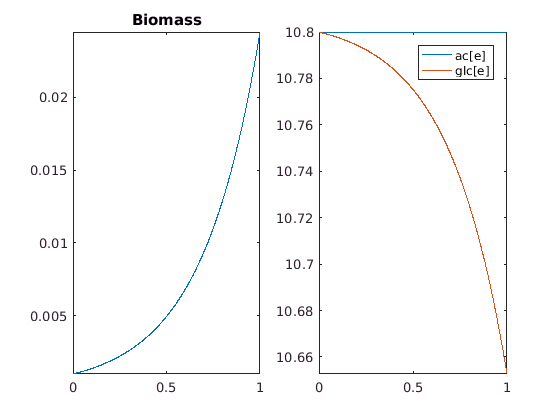

modeldinamic = model;
% For Recon3.0 model
% modeldinamic = changeRxnBounds (modeldinamic, 'EX_glc_D[e]', -20, 'l');
modeldinamic = changeRxnBounds (modeldinamic, 'EX_glc[e]', -20, 'b');
modeldinamic = changeRxnBounds (modeldinamic, 'EX_o2[e]', -1000, 'l');
modeldinamic = changeRxnBounds (modeldinamic, 'EX_ac[e]', -1000, 'l');
% For Recon3.0 model
% smi = {'EX_glc_D[e]' 'EX_ac[e]'}; 
smi = {'EX_glc[e]' 'EX_ac[e]'}; 
% exchange reaction for substrate in environment

smc = [10.8]; % Glucose, Acetate concentration (all in mM)

Xec = 0.001; % initial biomass
dt = 1.0/1000.0; % time steps
time = 1.0/dt; % simulation time

[concentrationMatrix, excRxnNames, timeVec,...
    biomassVec] = dynamicFBA(modeldinamic, smi, smc, Xec, dt, time, smi ); 

## Relax FBA

Find the minimal set of relaxations on bounds and steady-state constraint to make the FBA problem feasible.

modelrelax = modelalter;
FBArel = relaxFBA(modelrelax)

csense is not defined. We assume that all constraints are equalities.


FBArel =     stat: 1
       v: [7440×1 double]
       r: [5063×1 double]
       p: [7440×1 double]
       q: [7440×1 double]


The output `FBArel` contains solution fields, where 

`FBArel.v` is the reaction rate; 

`FBArel.r` is set of reactions that need relaxation on steady state constraints `S*v = b`;

`FBArel.p` is relaxation on lower bound of reactions;

`FBArel.r` is relaxation on upper bound of reactions;

## Flux enrichment analysis (FEA)

The flux enrichment analysis calculates the likelihood that a set of fluxes would belong to a subsystem or pathway.

## TIMING

The time to calculate the FEA is $<1$ second for any size of a model.

modelfea = model;
res = optimizeCbModel(modelfea,'max'); 
% say you are interested in enriching the active reactions
activeReactions = find(res.x) 

activeReactions =      8
    13
    20
    21
    22
    24
    28
    29
    30
    32


% You can also look for e.g. positive/negative/zeros flux reactions,
% that depends pretty much on the question.
% Now you look for the enrichement of reactions per subsystems
resultCell = FEA(modelfea, activeReactions, 'subSystems')

nonZeroInd =     66
    57
     7
     3
    56
    36
    41
    18
    97
    94


resultCell =     'P-value'        'Adjusted P-value'    'Group'                                                'Enriched set size'    'Total set size'
    [1.9643e-107]    [     1.5125e-105]    'Fatty acid oxidation'                                 [              178]    [           869]
    [ 2.7561e-48]    [      1.0611e-46]    'Eicosanoid metabolism'                                [               17]    [           257]
    [ 3.2497e-18]    [      8.3409e-17]    'Arachidonic acid metabolism'                          [                1]    [            73]
    [ 4.2230e-16]    [      8.1293e-15]    'Tyrosine metabolism'                                  [               14]    [           121]
    [ 7.5838e-15]    [      1.1679e-13]    'Fatty acid synthesis'                                 [               17]    [           126]
    [ 5.4384e-14]    [      6.9792e-13]    'Androgen and estrogen synthesis and metabolism'       [                1]    [            57]
    [ 8.7401e-12]    

## REFERENCES 

## REFERENCES 

[1] Orth, J. D., Thiele I., and Palsson, B. Ø.  What is flux balance analysis? *Nat. Biotechnol., *28(3), 245–248 (2010).

[2] Thiele, I., et al. A community-driven global reconstruction of human metabolism. *Nat. Biotechnol., *31(5), 419–425 (2013).

[3] Benyamini, T, Folger, O., Ruppin, E., Schlomi, T. Flux balance analysis accounting for metabolite dilution.* Genome Biology*., 11(4):R43 (2010).

[4] Smallbone, K., and Simeonidis, E. Flux balance analysis: A geometric perspective. *J Theor Biol*., 258: 311-315 (2009).

[5] Lewis, N.E., et al. Omic data from evolved E. coli are consistent with computed optimal growth from genome-scale models. *Mol Syst Biol*., 6:390 (2010).

[6] Mahadevan, R., Edwards, J.S., Doyle, F.J. Dynamic Flux Balance Analysis of Diauxic Growth in Escherichia coli. *Biophys J., *83(3):1331-1340 (2002).

[7] Varma A. and Palsson, B. Ø. Stoichiometric flux balance models quantitatively predict growth and metabolic by-product secretion in wild-type Escherichia coli W3110. *App Environ Microbiol*., 60(10):3724-3731 (1994).